FRM=2048;
MaxNumErrs=200;
MaxNumBits=1e7;
EbNo_vector=0:10;
BER_vector=zeros(size(EbNo_vector));
Modulator=comm.QPSKModulator('BitInput',true);
AWGN=comm.AWGNChannel;
DeModulator=comm.QPSKDemodulator('BitOutput',true);
BitError=comm.ErrorRate;
for EbNo=EbNo_vector
       snr=EbNo+10*log10(2);
       AWGN.EbNo=snr;
       numErrs=0;
       numBits=0;
       results=zeros(3,1);
       while((numErrs<MaxNumErrs)&&(numBits<MaxNumBits))
          u=randi([0 1],FRM,1);
          mod_sig=step(Modulator,u);
          rx_sig=step(AWGN,mod_sig);
          y=step(DeModulator,rx_sig);
          results=step(BitError,u,y);
          numErrs=results(2);
          numBits=results(3);
       end
       ber=results(1);
       bits=results(3); 
       reset(BitError);
       BER_vector(EbNo+1)=ber;
end
EbNoLin=10.^(EbNo_vector/10);
theoretical_results=0.5*erfc(sqrt(EbNoLin));
semilogy(EbNo_vector,BER_vector)
grid;
title('BER vs. EbNo-QPSK modulation');
xlabel('Eb/No(dB)');
ylabel('BER');
hold;

已锁定最新绘图


semilogy(EbNo_vector,theoretical_results,'dr');
hold;

已发布最新绘图


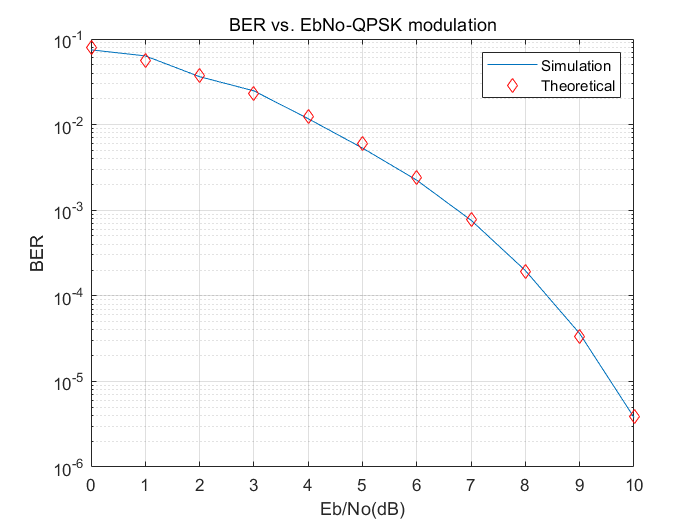

legend('Simulation','Theoretical');